### Загрузка данных

- `spectra.csv` -- содержит интенсивности излучения,

- `star_names.csv` -- содержит имена звезд,

- `lambda_start.csv` -- содержит стартовую длину волны

- `lambda_delta.csv` -- содержит расстояние между двумя соседними длинами волн в исследуемом интервале.

spectra     = readmatrix("spectra.csv")

spectra = 1.0e-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


starNames   = readmatrix("star_names.csv");
lambdaStart = readmatrix("lambda_start.csv");
lambdaDelta = readmatrix("lambda_delta.csv");

### Подготовка данных

stars_count = length(starNames);
lambda_len = length(spectra(:,1));
lambda_end = lambdaStart + (lambda_len-1)*lambdaDelta;
lambda = lambdaStart : lambdaDelta : lambda_end;
lambda_Ha = 656.28

lambda_Ha = 656.2800

lightspeed = 3e8

lightspeed = 300000000

### Минимальные интенсивности

min_indexes = zeros(1, stars_count);
min_intensity = zeros(1, stars_count);
for i = 1 : stars_count
    [min_intensity(i), min_indexes(i)] = min(spectra(:,i));
end

Относительные смещения

Z = zeros(1, stars_count);
for i = 1 : stars_count
    lambda_Ha_obs = lambda(min_indexes(i));
    Z(i) = (lambda_Ha_obs/656.28)-1;
end



### Cкорости

speed = zeros(1, stars_count);
for i = 1 : stars_count
    speed(i) = Z(i)*lightspeed;
end

### Построение графика

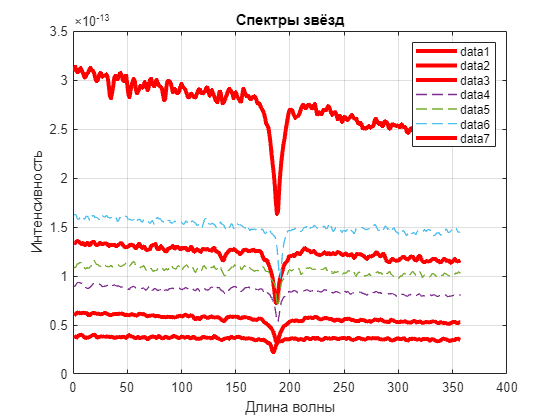

fg1  = figure;


for i = 1 : stars_count
    if speed(i)<0
        plot(spectra(:,i), 'r', 'LineWidth', 3);
    end
    if speed(i)>0
        plot(spectra(:,i), '--', 'LineWidth', 1);
    end
    hold on;
end
xlabel('Длина волны')
ylabel('Интенсивность')
grid on
title('Спектры звёзд')
legend()
saveas(fg1, 'star1.png')